Theodore Janson

260868223

ECSE 403

Lab Assignment 3

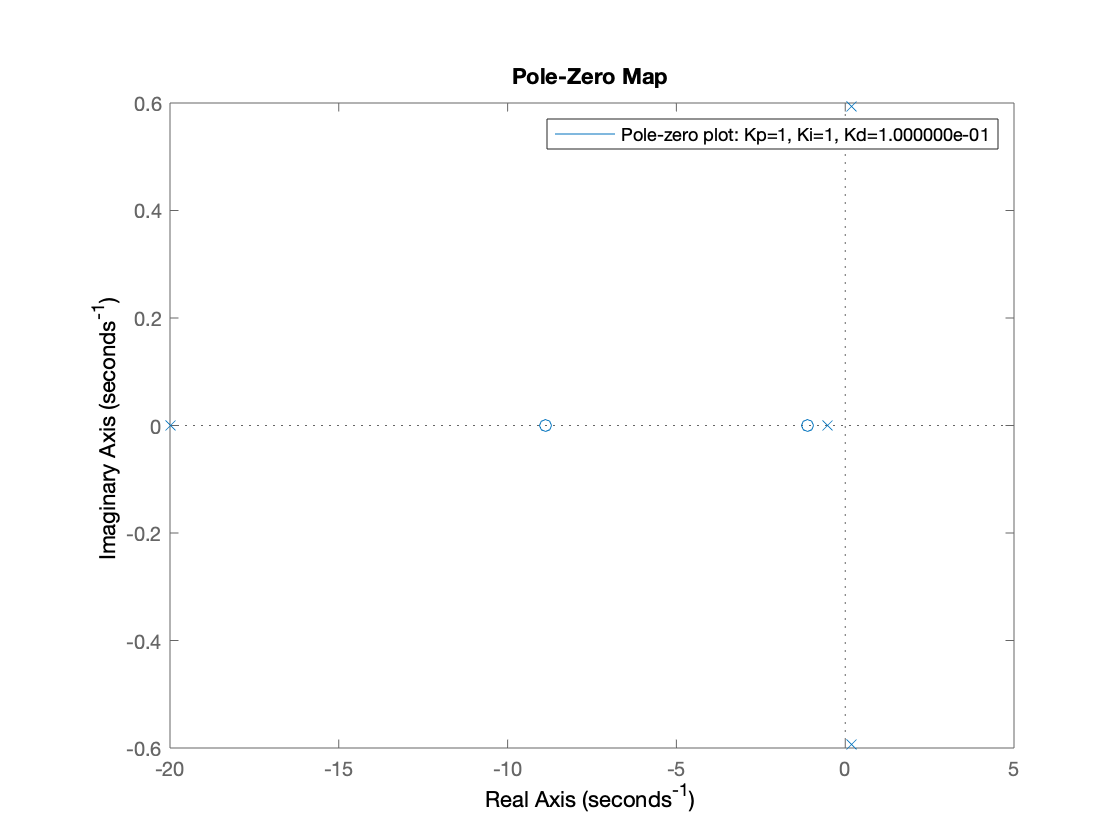

Jm = 0.01; %kgm^2 , inertia of the rotor and shaft
b = 0.001; %Nmsec , viscous friction coefficient
Ke = 0.02; %Vsec  , back emf constant
Kt = 0.02; %Nm/A  , motor torque constant
Ra = 10;   %Ω     , armature resitance
La = 0.5;

a0 = 0;
a1 = (b+(Kt*Ke)/Ra)/Jm; %divide equation Jm to get unity coefficient for θ''
b0 = Kt / (Ra*Jm);


A2 = [0 1 0 ; 0 -b/Jm Kt/Jm ; 0 -Ke/La -Ra/La];
B2 = [0 ; 0 ; 1/La];
C2 = [1 0 0 ];
sys = ss(A2,B2,C2,0);
Kd = [0.1 1 10 100];
Kp = [0.1 1 10 100];
Ki = [0.1 1 10 100];

%kd varies
Gd = pid(Kp(1,2), Ki(1,2), Kd(1,1));
Gd = feedback(Gd*sys, 1);
pzmap(ss(Gd))
title = 'Pole-zero plot: Kp=1, Ki=1, Kd=%d';
legend(sprintf(title,Kd(1,1)))

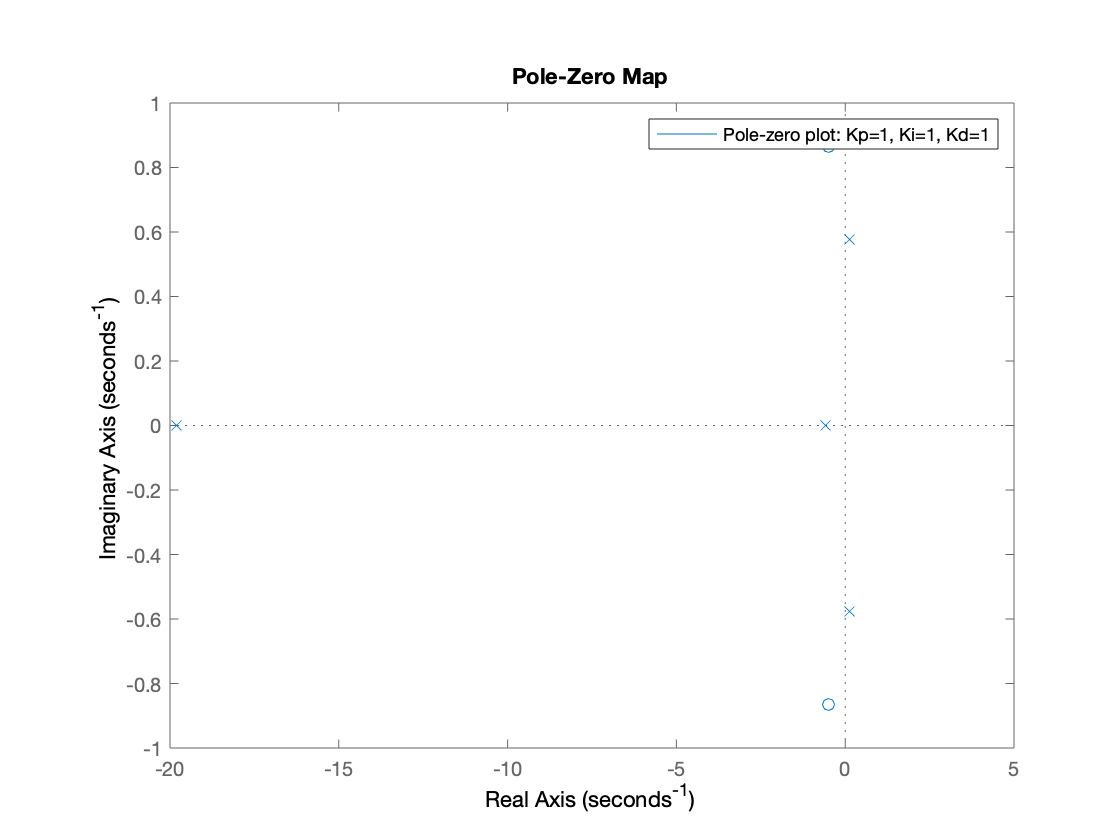


Gd = pid(Kp(1,2), Ki(1,2), Kd(1,2));
Gd = feedback(Gd*sys, 1);
pzmap(ss(Gd))
title = 'Pole-zero plot: Kp=1, Ki=1, Kd=%d';
legend(sprintf(title,Kd(1,2)))

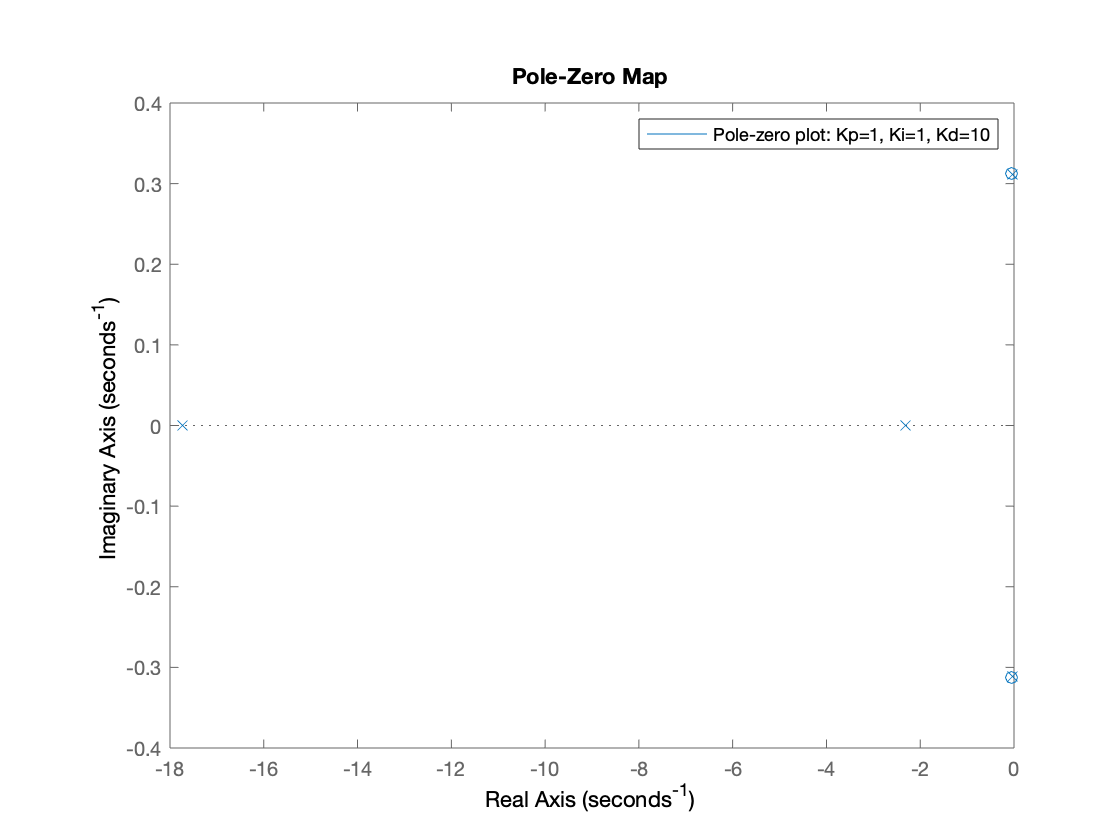


Gd = pid(Kp(1,2), Ki(1,2), Kd(1,3));
Gd = feedback(Gd*sys, 1);
pzmap(ss(Gd))
title = 'Pole-zero plot: Kp=1, Ki=1, Kd=%d';
legend(sprintf(title,Kd(1,3)))

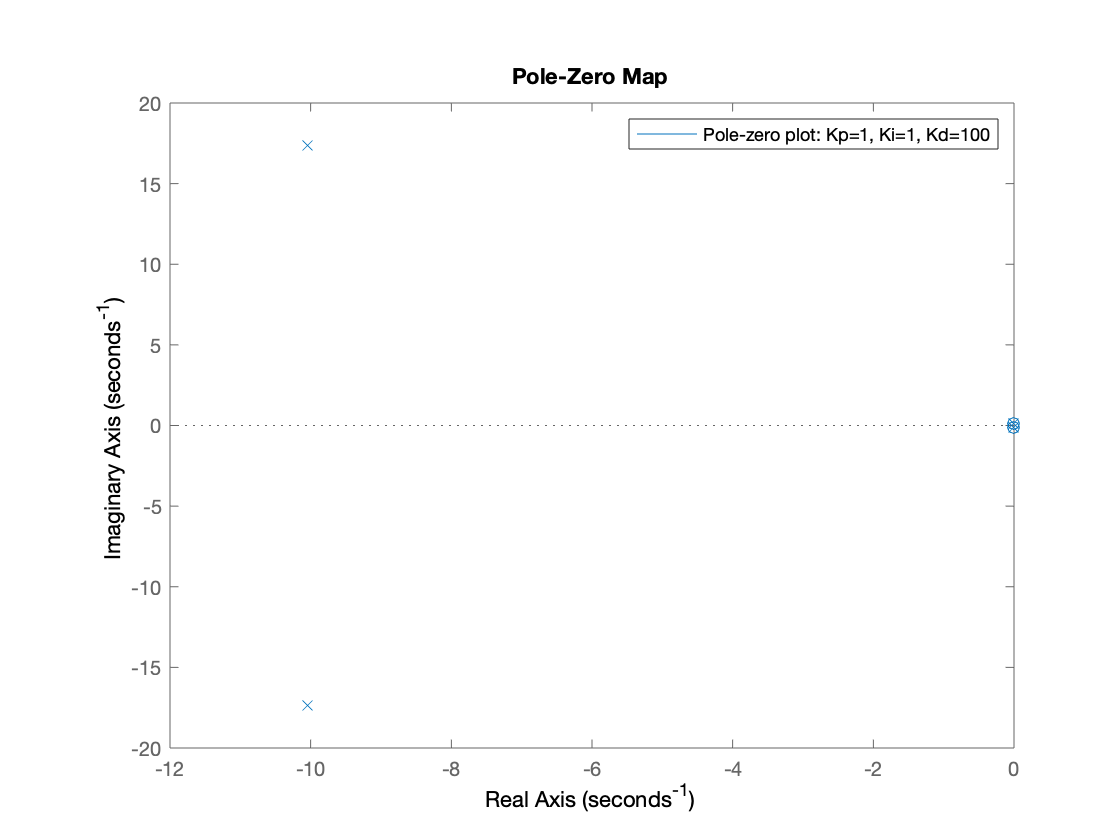


Gd = pid(Kp(1,2), Ki(1,2), Kd(1,4));
Gd = feedback(Gd*sys, 1);
pzmap(ss(Gd))
title = 'Pole-zero plot: Kp=1, Ki=1, Kd=%d';
legend(sprintf(title,Kd(1,4)))

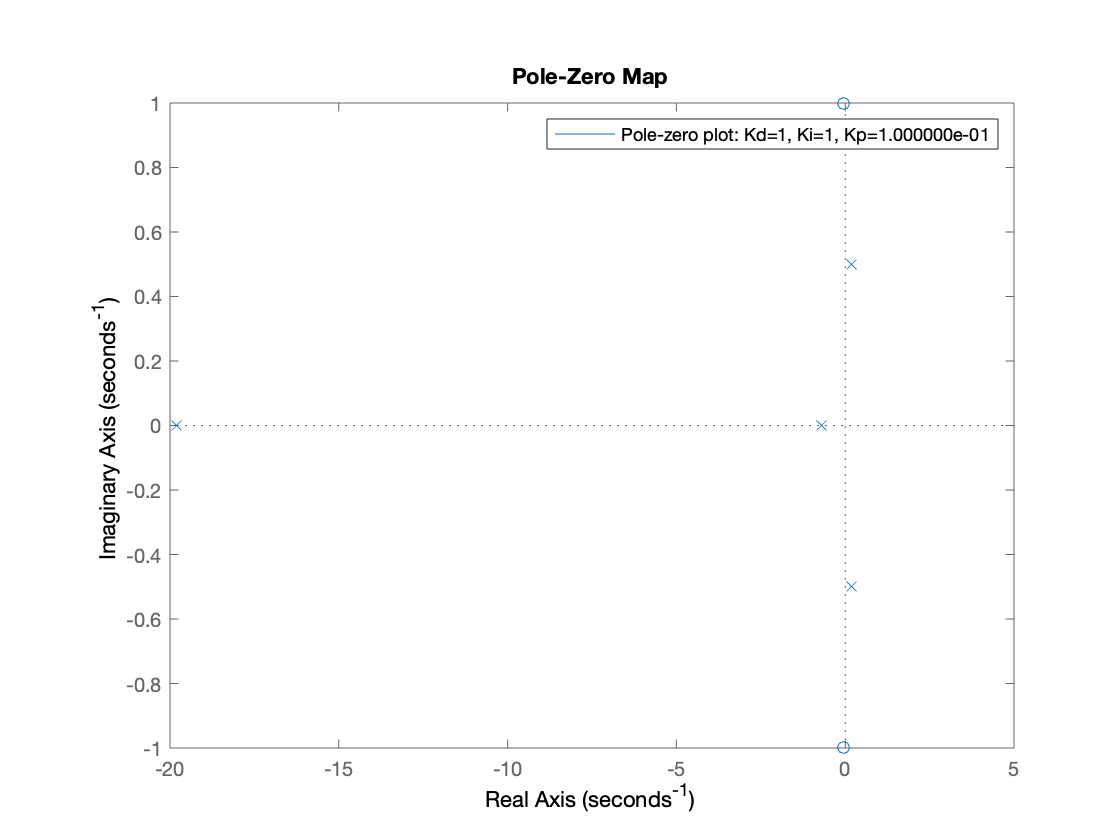


%kp varies 

Gp = pid(Kp(1,1), Ki(1,2), Kd(1,2));
Gp = feedback(Gp*sys, 1);
pzmap(ss(Gp))
title = 'Pole-zero plot: Kd=1, Ki=1, Kp=%d';
legend(sprintf(title, Kp(1,1)))

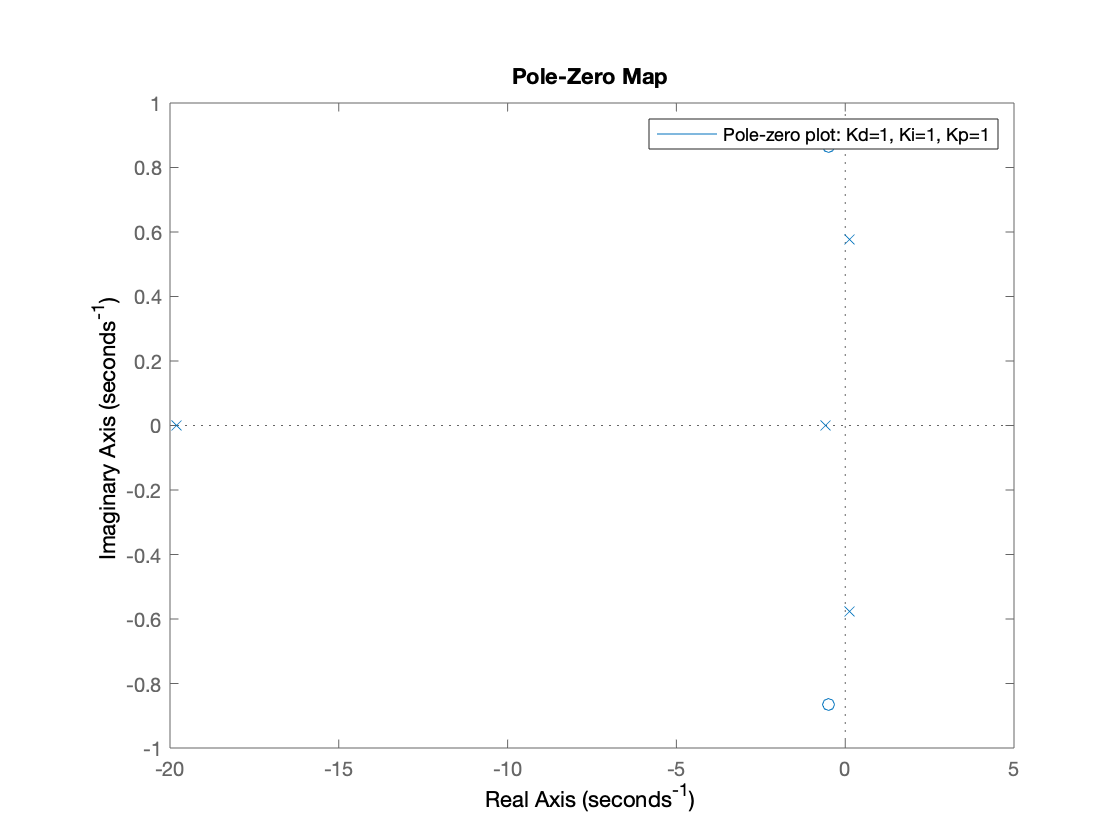


Gp = pid(Kp(1,2), Ki(1,2), Kd(1,2));
Gp = feedback(Gp*sys, 1);
pzmap(ss(Gp))
title = 'Pole-zero plot: Kd=1, Ki=1, Kp=%d';
legend(sprintf(title, Kp(1,2)))

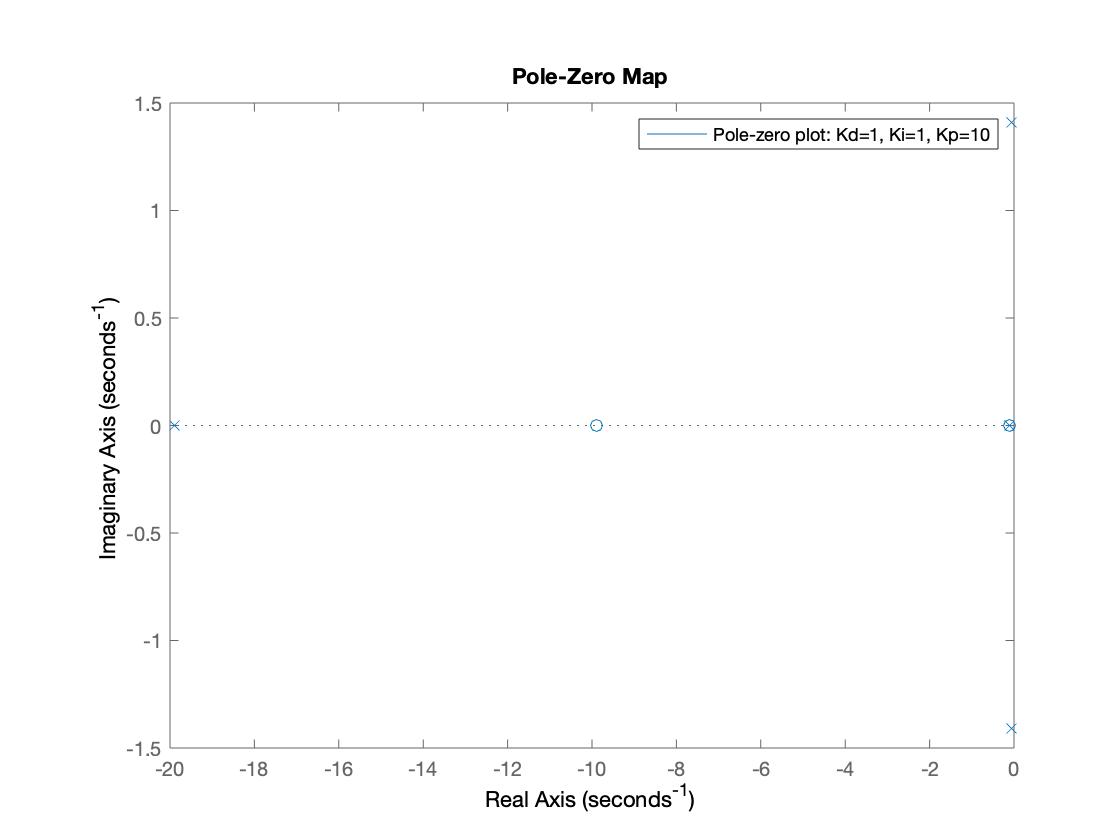


Gp = pid(Kp(1,3), Ki(1,2), Kd(1,2));
Gp = feedback(Gp*sys, 1);
pzmap(ss(Gp))
title = 'Pole-zero plot: Kd=1, Ki=1, Kp=%d';
legend(sprintf(title, Kp(1,3)))

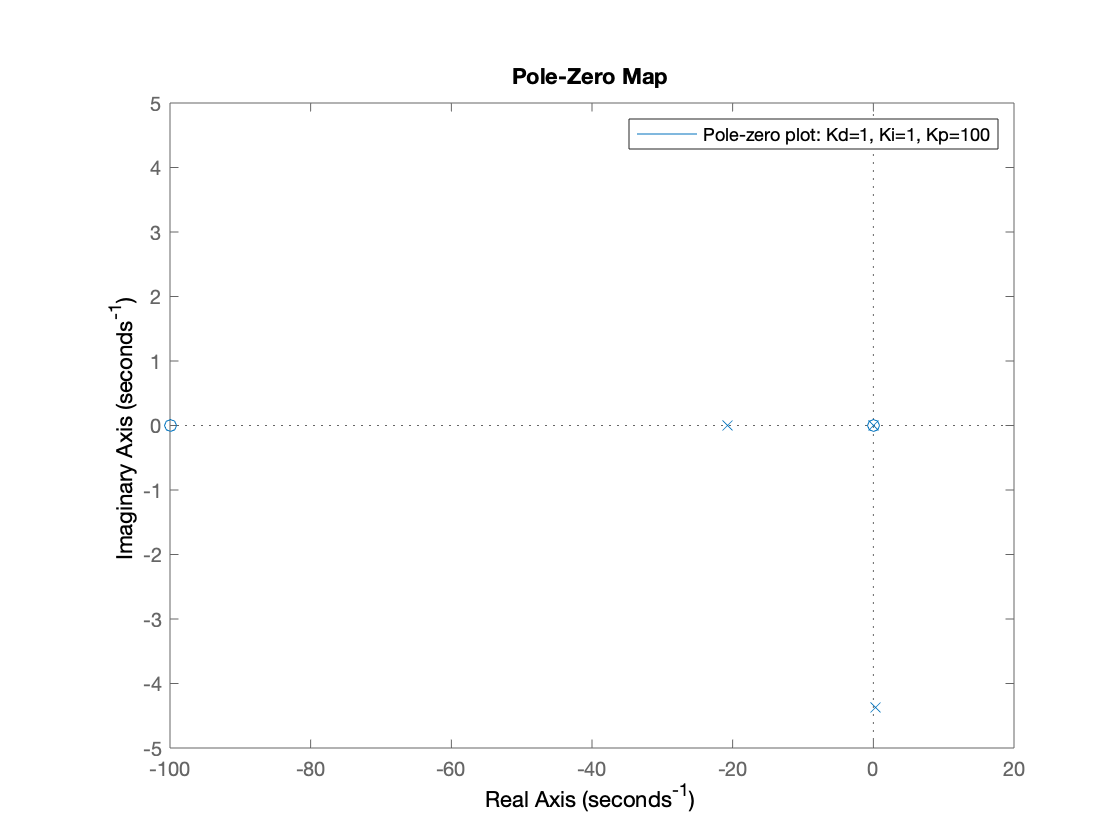


Gp = pid(Kp(1,4), Ki(1,2), Kd(1,2));
Gp = feedback(Gp*sys, 1);
pzmap(ss(Gp))
title = 'Pole-zero plot: Kd=1, Ki=1, Kp=%d';
legend(sprintf(title, Kp(1,4)))

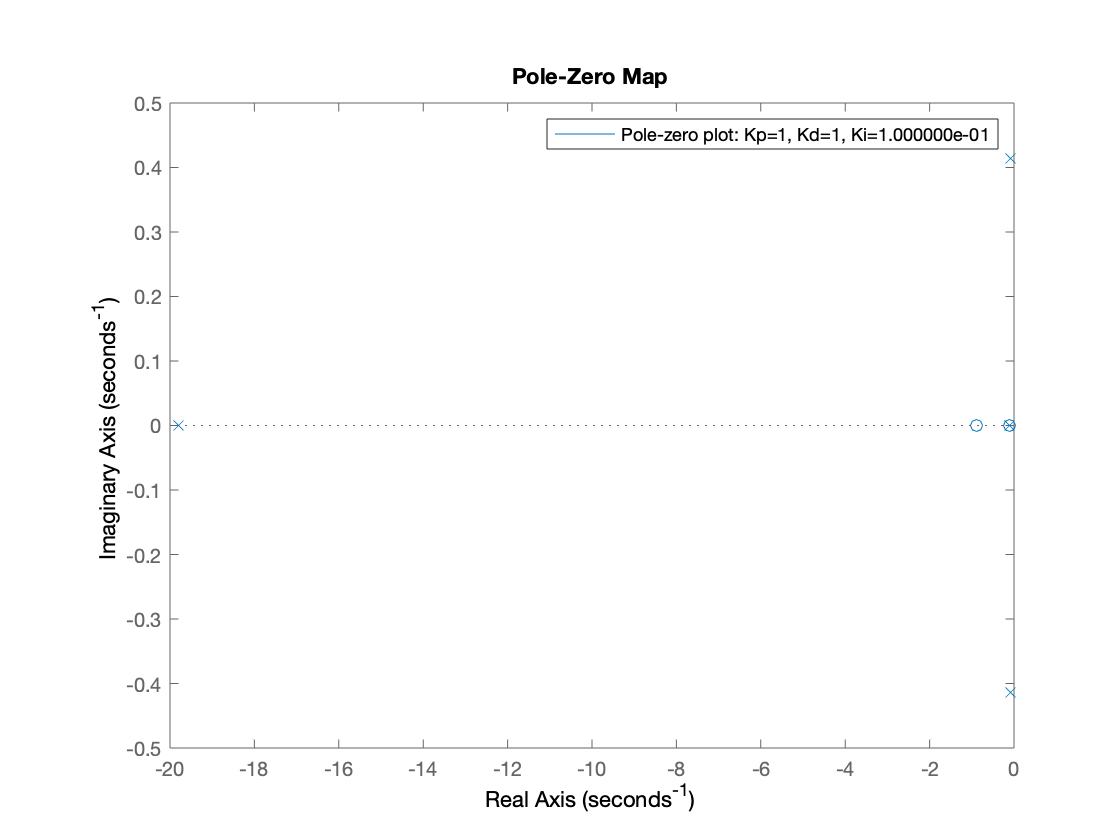


%ki varies
Gi = pid(Kp(1,2), Ki(1,1), Kd(1,2));
Gi = feedback(Gi*sys, 1);
pzmap(ss(Gi))
title = 'Pole-zero plot: Kp=1, Kd=1, Ki=%d';
legend(sprintf(title,Ki(1,1)))

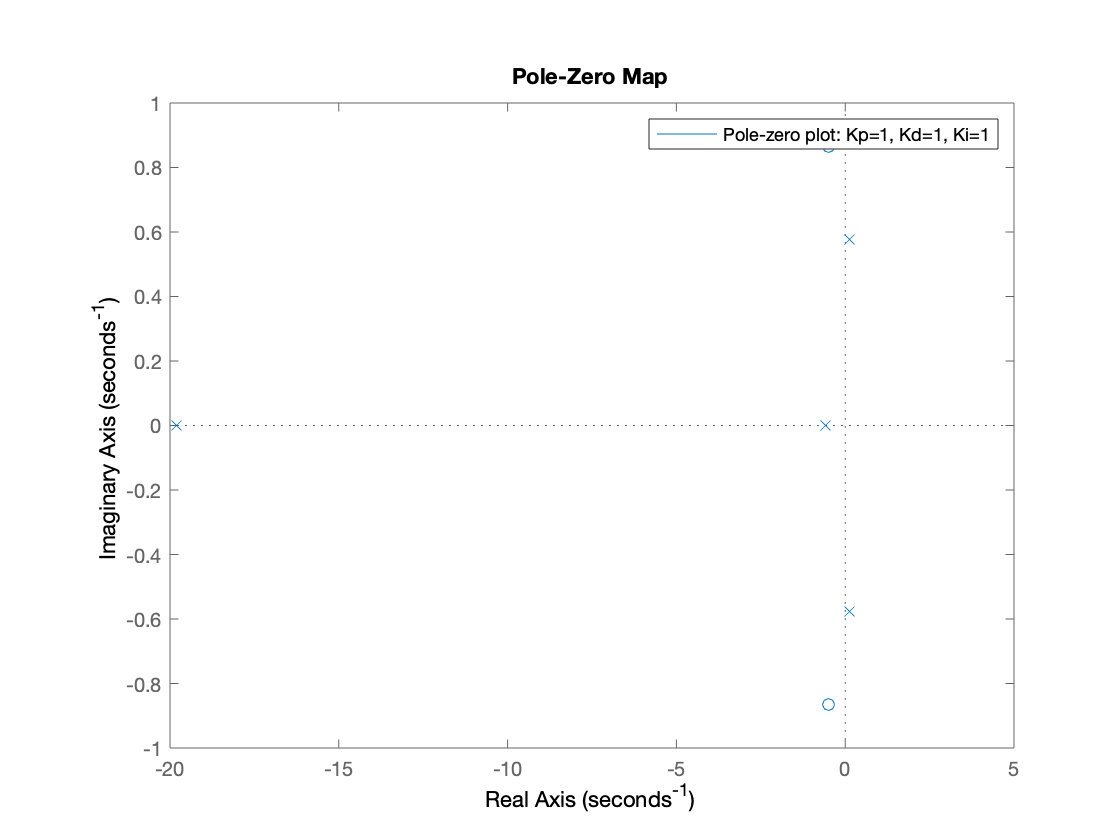


Gi = pid(Kp(1,2), Ki(1,2), Kd(1,2));
Gi = feedback(Gi*sys, 1);
pzmap(ss(Gi))
title = 'Pole-zero plot: Kp=1, Kd=1, Ki=%d';
legend(sprintf(title,Ki(1,2)))

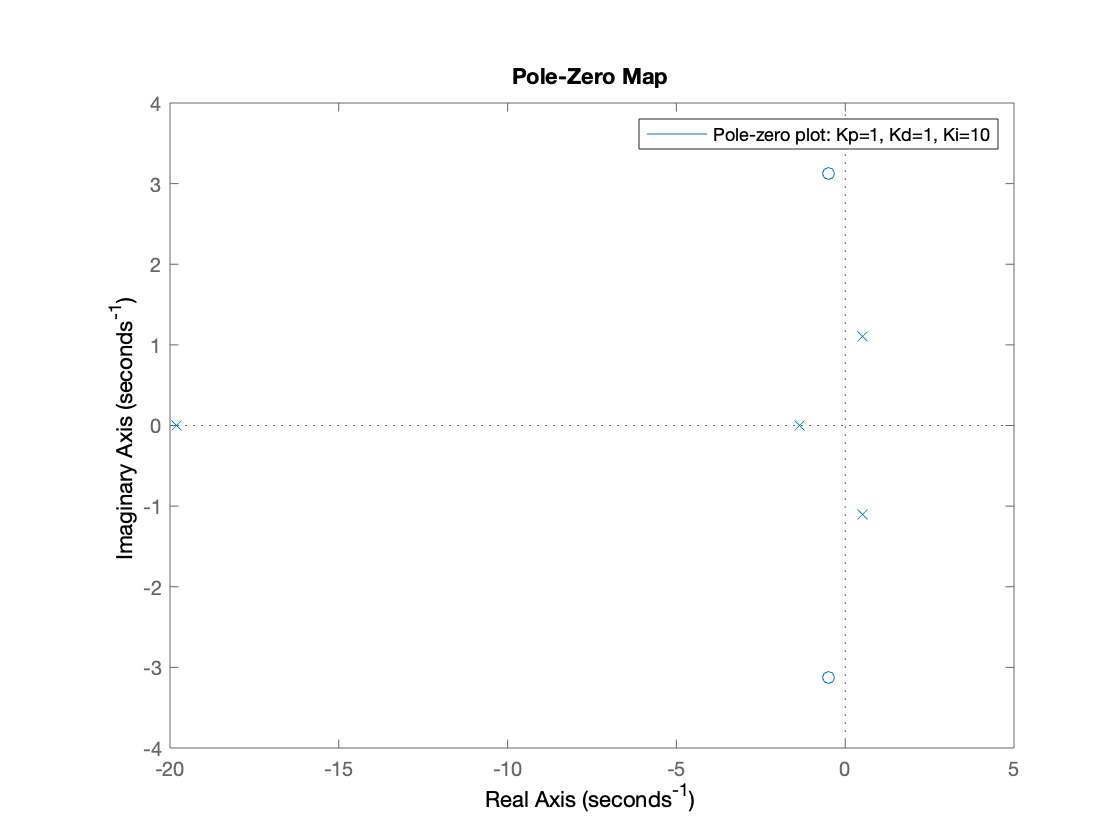


Gi = pid(Kp(1,2), Ki(1,3), Kd(1,2));
Gi = feedback(Gi*sys, 1);
pzmap(ss(Gi))
title = 'Pole-zero plot: Kp=1, Kd=1, Ki=%d';
legend(sprintf(title,Ki(1,3)))

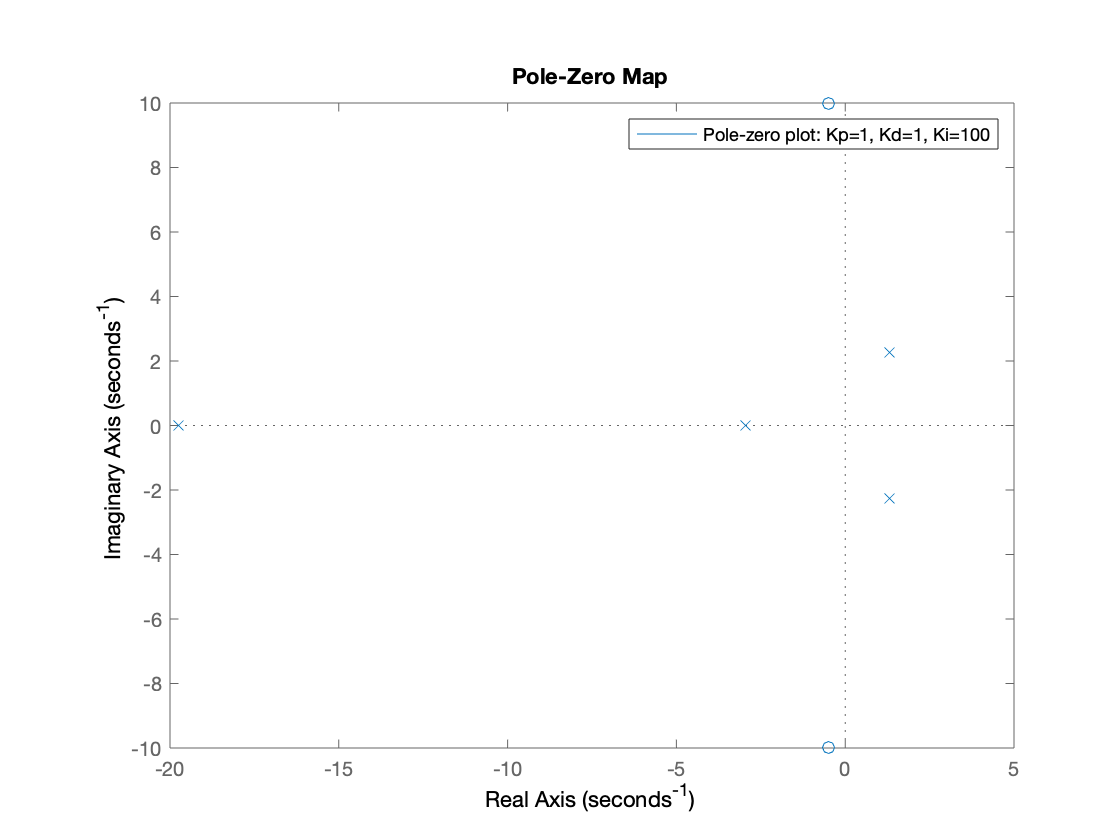


Gi = pid(Kp(1,2), Ki(1,4), Kd(1,2));
Gi = feedback(Gi*sys, 1);
pzmap(ss(Gi))
title = 'Pole-zero plot: Kp=1, Kd=1, Ki=%d';
legend(sprintf(title,Ki(1,4)))






% % %Theoretical 
% G1 = tf([b0], [1 a1 a0]);
% w = [0.1, 1000];
% figure(1);
% bode(G1, w);
% % 
% % %Expeimental
% x = [-1 0 1 2 3];
% y = [20*log10(33) 20*log10(1.93) 20*log10(0.1942) 20*log10(0.01925) 20*log10(0.001923)];
% plot(x, y)
% legend('Experimental Bode Plot') 
% xlabel('log10(w)') 
% ylabel('20log(gain)') 
% 
% 
% % %Theoretical
% G2 = tf([b0], [1 a1 b0]);
% figure(1);
% bode(G2, w);
% % 
% % %Expeimental
% x2 = [-1 0 1 2 3];
% y2 = [20*log10(1.073) 20*log10(0.21) 20*log10(0.03918) 20*log10(0.00379) 20*log10(0.000377)];
% plot(x2, y2)
% legend('Experimental Bode Plot') 
% xlabel('log10(w)') 
% ylabel('20log(gain)') 
% 
% 
% %Theoretical 
% A2 = [0 1 0 ; 0 -b/Jm Kt/Jm ; 0 -Ke/La -Ra/La];
% B2 = [0 ; 0 ; 1/La];
% C2 = [1 0 0 ];
% [b5,a5] = ss2tf(A2,B2,C2,0);
% G5 = tf([b5],[a5])
% bode(G5, wmin_max);
% 
% 
% % %Expeimental
% x3 = [-1 0 1 2 3];
% y3 = [20*log10(33.1) 20*log10(2.122) 20*log10(0.1941) 20*log10(0.01923) 20*log10(0.001923)];
% plot(x3, y3)
% legend('Experimental Bode Plot') 
% xlabel('log10(w)') 
% ylabel('20log(gain)') 





